# **Exploring brain-behaviour relationships in the tbfMRI choir-singing dataset**

The results from the behavioural analyses are:

- Communication index 

- Responsive Speech

- SIS participation and role function subscale

- Caregiver burden index (not included in this analisis)

clear all
% Specify directories and patients
data_path='/Volumes/LASA/Aphasia_project/tb-fMRI/results/post-pre_diff_images/TU/';
output_path='/Volumes/LASA/Aphasia_project/tb-fMRI/results/behaviour/';
addpath '/Users/noeliamartinezmolina/Documents/GitHub/tbfMRI_LASA_current_code/notebooks/behaviour'; %add code path

First, we will extract the values from the significant behavioural variables for each patient:

% Import behavioural data and extract variables for the fMRI sample (N=28)
Data = fileread(fullfile(output_path,'LASA_questionnaires_CVA_TBI_beh_fMRI.csv'));
Data = strrep(Data, ',', '.');
FID = fopen('LASA_questionnaires_CVA_TBI_beh_fMRI_fixed.csv', 'w');
fwrite(FID, Data, 'char');
fclose(FID);
importfile_behaviour('LASA_questionnaires_CVA_TBI_beh_fMRI_fixed.csv');
Comm_Idx_int_all=ans.Communication_index_INT;
Resp_Speech_Idx_int_all=ans.Change_WAB_naming_repetition_intervention;
%SIS_part_fun_int_all=;
ID_BIDS_all=ans.ID_num;

Second, we will extract the peak values from the coordinates with significant results in the paired T-test and flexible factorial for the corresponding contrasts:

- Paired T, Tydyy-Uulaa Singing along vs rest: PoG R (48,-16,39)

- Paired T, Tydyy-Uulaa Singing along vs singing from memory: PreG R/IFG R (58,4,29)

- Flexible ABvsBA&TP2vsTP1, Tydyy-Uulaa Singing along vs rest: STG R (48,-12,15)

% Save peak value and contrast name to variable
peak1=[48,-16,39];% paired T singavsrest MNI coord in mm
peak2=[58,4,29]; %paired T singavssingm MNI coord in mm
peak3=[48,-12,15]; %flexible singavsrest MNI coord in mm
contrast1='Sing_along>Baseline';
contrast2='Sing_along>Sing_mem';

## Contrast 1: Paired T test Tydyy-Uulaa Sing along vs Rest

x =     6.8118
    0.7318
   -1.7848
   13.3842
    9.2769
    3.6763
    8.7240
    4.5041
    8.9731
    6.8395


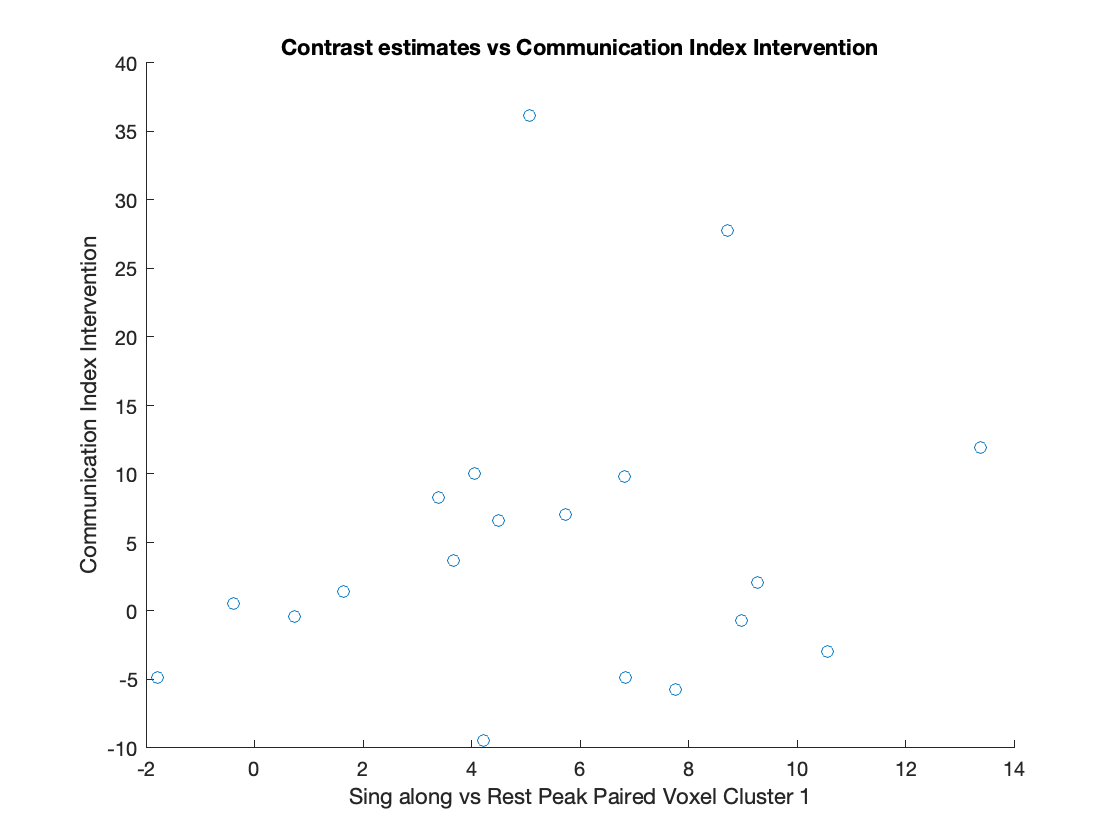

% Get the image filenames
filenames_contrast1= dir(fullfile(data_path,contrast1));
filenames_contrast1(ismember({filenames_contrast1.name},{'.','..'}))=[];
% Get mean cluster intensity for all patients
for i=1:size(filenames_contrast1,1)    
    V=spm_vol(fullfile(data_path,contrast1,filenames_contrast1(i).name)); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    idx=find(XYZmm(1,:)==peak1(1,1) & XYZmm(2,:)==peak1(1,2) & XYZmm(3,:)==peak1(1,3)); %Get the intensity value for the peak
    XYZmm(:,idx);
    [Xvox, Yvox, Zvox]=ind2sub(size(Y(:,:,:,1)),idx);
    int=Y(Xvox,Yvox,Zvox,:);
    [~,name,ext] =fileparts(filenames_contrast1(i).name);
    pa_int_peak1{i,1}=str2num(name(end-1:end)); %Save the patient ID in BIDS
    pa_int_peak1{i,2}=int;% Save intensity value for the peak from all patients
end

%% Get behavioural values from the patients with existing images
ID_BIDS_pat=cell2mat(pa_int_peak1(:,1));
[idx_pat,iall,i] = intersect(ID_BIDS_all,ID_BIDS_pat);
Comm_Idx_int_pat_contrast1=Comm_Idx_int_all(iall,:);
Resp_Speech_Idx_int_pat_contrast1=Resp_Speech_Idx_int_all(iall,:);

% Remove patients with NaN values in behaviour
if sum(isnan(Comm_Idx_int_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1=find(isnan(Comm_Idx_int_pat_contrast1(:,1)));
    Comm_Idx_int_pat_contrast1(NAN_Index_contrast1,:)=[];
    pa_int_peak1_comm=cell2mat(pa_int_peak1(:,2));
    pa_int_peak1_comm(NAN_Index_contrast1,:)=[];
end
%% Plot Intensity against behaviour for the peak coordinate
for p=1:size(peak1,1)
        y=Comm_Idx_int_pat_contrast1;
        if exist('pa_int_peak1_comm')==1
            x=pa_int_peak1_comm;
        else
            x=cell2mat(pa_int_peak1(:,2))
        end
        figure
        scatter(x,y)
        title ('Contrast estimates vs Communication Index Intervention'), xlabel(['Sing along vs Rest Peak Paired Voxel Cluster ' num2str(p)]), ylabel ('Communication Index Intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_PairedT_SingavsRest_Communication_Index_' num2str(p) '.jpg'])
        save('Communication_Index_int_singavsrest','x','y')
        CI_singavsrest_T=table(x,y);
        writetable(CI_singavsrest_T, 'CI_singavsrest_T.xlsx')
end


% correlation
[rho_peak1,pval_peak1] = corr(x,y,'Type','Pearson')

rho_peak1 = 0.1974

pval_peak1 = 0.4180

[rho_peak1,pval_peak1] = corr(x,y,'Type','Spearman')

rho_peak1 = 0.1439

pval_peak1 = 0.5555

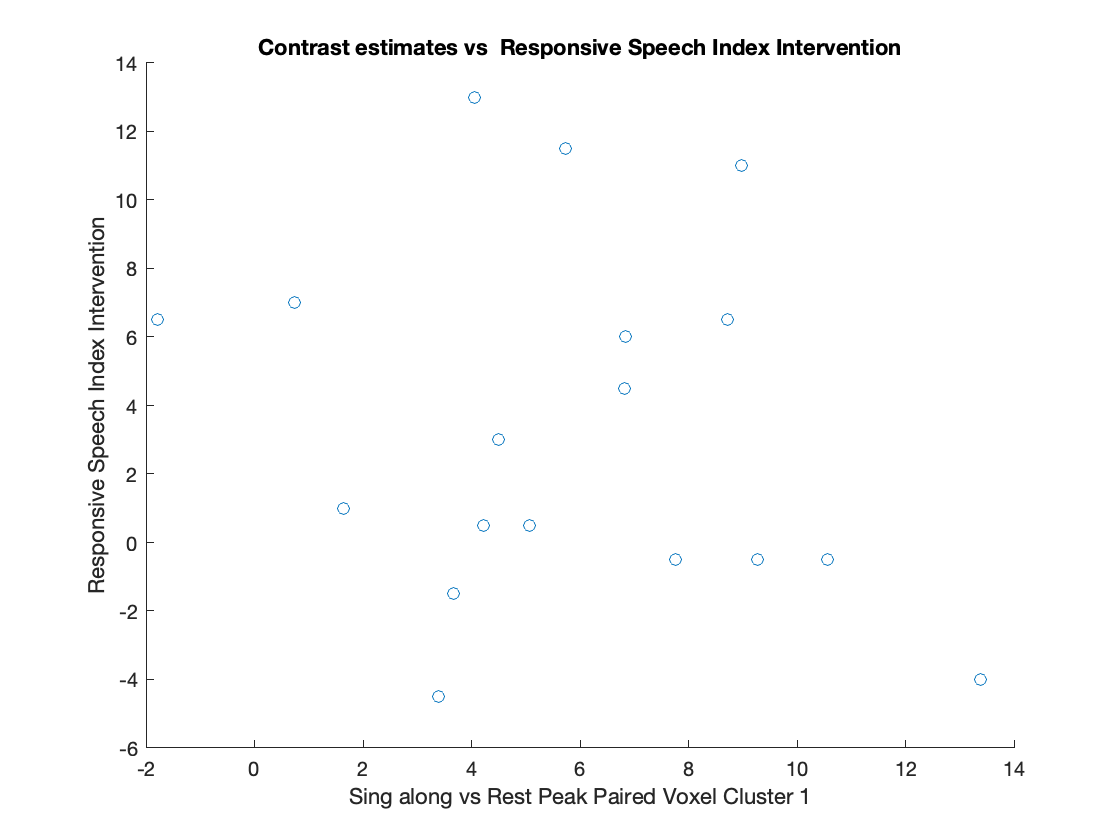

clear x y

% Remove patients with NaN values in behaviour
if sum(isnan(Resp_Speech_Idx_int_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1=find(isnan(Resp_Speech_Idx_int_pat_contrast1(:,1)));
    Resp_Speech_Idx_int_pat_contrast1(NAN_Index_contrast1,:)=[];
    pa_int_peak1_resp=cell2mat(pa_int_peak1(:,2));
    pa_int_peak1_resp(NAN_Index_contrast1,:)=[];
end
%% Plot Intensity against behaviour for the peak coordinate
for p=1:size(peak1,1)
        y=Resp_Speech_Idx_int_pat_contrast1;
           if exist('pa_int_peak1_resp')==1
            x=pa_int_peak1_resp;
        else
            x=cell2mat(pa_int_peak1(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs  Responsive Speech Index Intervention'), xlabel(['Sing along vs Rest Peak Paired Voxel Cluster ' num2str(p)]), ylabel ('Responsive Speech Index Intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_PairedT_SingavsRest_Responsive_Speech_Index_' num2str(p) '.jpg'])
        save('Responsive_Speech_Index_int_singavsrest','x','y')
        RSI_singavsrest_T=table(x,y);
        writetable(RSI_singavsrest_T, 'RSI_singavsrest_T.xlsx')
end


% correlation
[rho_peak1,pval_peak1] = corr(x,y,'Type','Pearson')

rho_peak1 = -0.2160

pval_peak1 = 0.3893

[rho_peak1,pval_peak1] = corr(x,y,'Type','Spearman')

rho_peak1 = -0.2219

pval_peak1 = 0.3747

clear x y


## Contrast 1: Flexible AB>BAxTP2>TP1 Tydyy-Uulaa Sing along vs Rest

% Get peak voxel intensity for all patients
for i=1:size(filenames_contrast1,1)
    V=spm_vol(fullfile(data_path,contrast1,filenames_contrast1(i).name)); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    idx=find(XYZmm(1,:)==peak3(1,1) & XYZmm(2,:)==peak3(1,2) & XYZmm(3,:)==peak3(1,3)); %Get the intensity value for the peak
    XYZmm(:,idx);
    [Xvox, Yvox, Zvox]=ind2sub(size(Y(:,:,:,1)),idx);
    int=Y(Xvox,Yvox,Zvox,:);
    [~,name,ext] =fileparts(filenames_contrast1(i).name);
    pa_int_peak3{i,1}=str2num(name(end-1:end)); %Save the patient ID in BIDS
    pa_int_peak3{i,2}=int;% Save intensity value for the peak from all patients
end

%% Get behavioural values from the patients with existing images
ID_BIDS_pat=cell2mat(pa_int_peak3(:,1));
[idx_pat,iall,i] = intersect(ID_BIDS_all,ID_BIDS_pat);
Comm_Idx_int_pat_contrast1f=Comm_Idx_int_all(iall,:);
Resp_Speech_Idx_int_pat_contrast1f=Resp_Speech_Idx_int_all(iall,:)

Resp_Speech_Idx_int_pat_contrast1f =     4.5000
    7.0000
    6.5000
   -4.0000
   -0.5000
   -1.5000
    6.5000
    3.0000
   11.0000
    6.0000


x =     7.7555
    2.2551
   -2.7638
    8.7550
  -32.0012
    2.9597
    8.8263
   -2.9553
   -1.0006
    2.7671


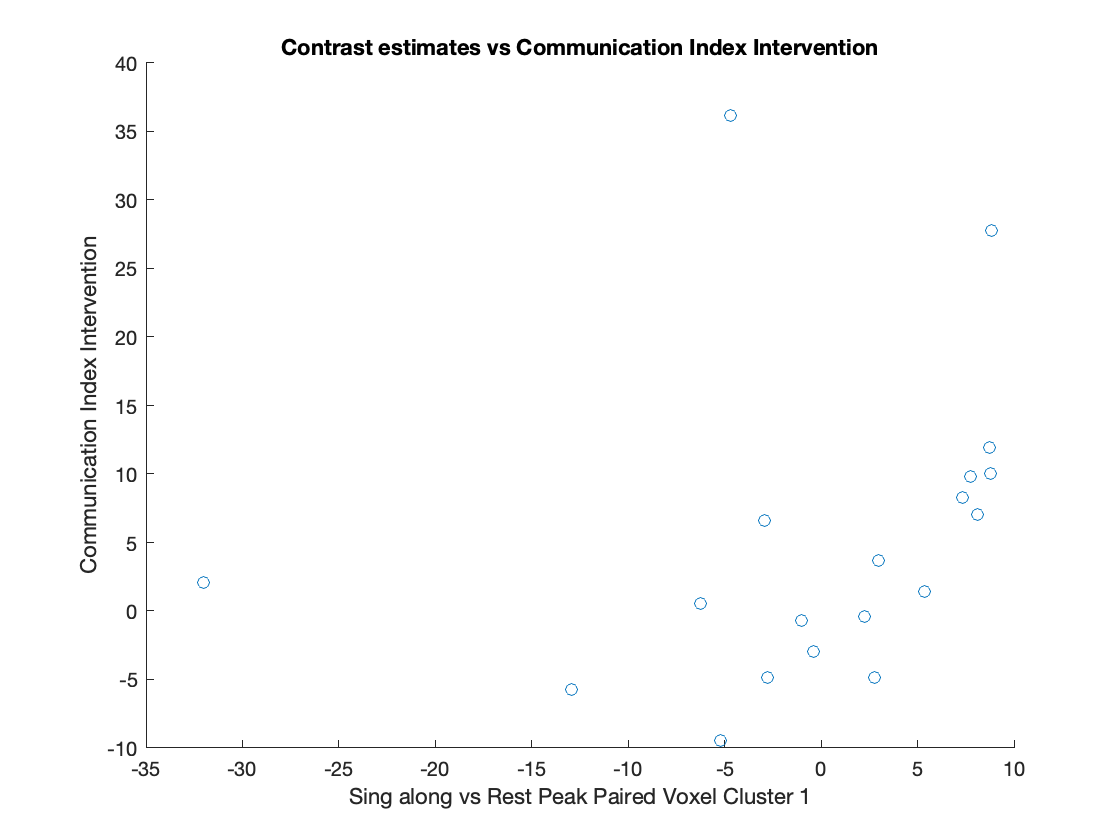


% Remove patients with NaN values in behaviour
if sum(isnan(Comm_Idx_int_pat_contrast1f(:,1)))~=0
    NAN_Index_contrast1f=find(isnan(Comm_Idx_int_pat_contrast1f(:,1)));
    Comm_Idx_int_pat_contrast1f(NAN_Index_contrast1f,:)=[];
    pa_int_peak3_comm=cell2mat(pa_int_peak3(:,2));
    pa_int_peak3_comm(NAN_Index_contrast1f,:)=[];
end
    
%% Plot Intensity against behaviour for the peak coordinate
for p=1:size(peak3,1)
        y=Comm_Idx_int_pat_contrast1f;
           if exist('pa_int_peak3_comm')==1
            x=pa_int_peak3_comm;
        else
            x=cell2mat(pa_int_peak3(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs Communication Index Intervention'), xlabel(['Sing along vs Rest Peak Paired Voxel Cluster ' num2str(p)]), ylabel ('Communication Index Intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_flex_SingavsRest_Communication_Index_' num2str(p) '.jpg'])
        save('Communication_Index_int_singavsrest_flex','x','y')
        CI_singavsrest_F=table(x,y);
        writetable(CI_singavsrest_F, 'CI_singavsrest_F.xlsx')
end


% correlation
[rho_peak3,pval_peak3] = corr(x,y,'Type','Pearson')

rho_peak3 = 0.2700

pval_peak3 = 0.2635

[rho_peak3,pval_peak3] = corr(x,y,'Type','Spearman')

rho_peak3 = 0.5860

pval_peak3 = 0.0096

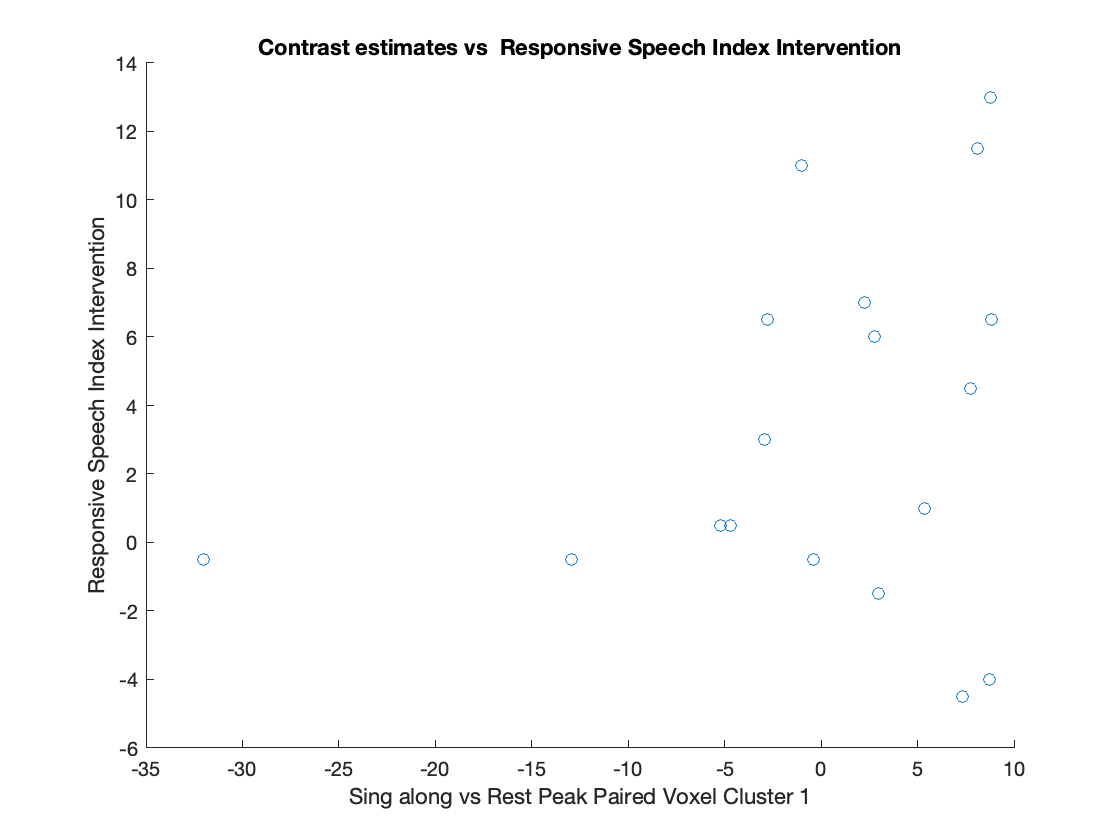

clear x y

% Remove patients with NaN values in behaviour
if sum(isnan(Resp_Speech_Idx_int_pat_contrast1f(:,1)))~=0
    NAN_Index_contrast1f=find(isnan(Resp_Speech_Idx_int_pat_contrast1f(:,1)));
    Resp_Speech_Idx_int_pat_contrast1f(NAN_Index_contrast1f,:)=[];
    pa_int_peak3_resp=cell2mat(pa_int_peak3(:,2));
    pa_int_peak3_resp(NAN_Index_contrast1f,:)=[];
end

%% Plot Intensity against behaviour for the peak coordinate
for p=1:size(peak3,1)
        y=Resp_Speech_Idx_int_pat_contrast1f;
           if exist('pa_int_peak3_resp')==1
            x=pa_int_peak3_resp;
        else
            x=cell2mat(pa_int_peak3(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs  Responsive Speech Index Intervention'), xlabel(['Sing along vs Rest Peak Paired Voxel Cluster ' num2str(p)]), ylabel ('Responsive Speech Index Intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_flex_SingavsRest_Responsive_Speech_Index_' num2str(p) '.jpg'])
        save('Responsive_Speech_Index_int_singavsrest_flex','x','y')
        RSI_singavsrest_F=table(x,y);
        writetable(RSI_singavsrest_F, 'RSI_singavsrest_F.xlsx')
end


% correlation
[rho_peak3,pval_peak3] = corr(x,y,'Type','Pearson')

rho_peak3 = 0.2705

pval_peak3 = 0.2776

[rho_peak3,pval_peak3] = corr(x,y,'Type','Spearman')

rho_peak3 = 0.2466

pval_peak3 = 0.3224

clear x y


## Contrast 2: Paired T test Tydyy-Uulaa Sing along vs Sing mem

x =    -0.0902
   10.1334
    7.7304
    6.8381
    6.7748
    7.7198
    5.9340
    1.4450
    5.6253
    4.2750


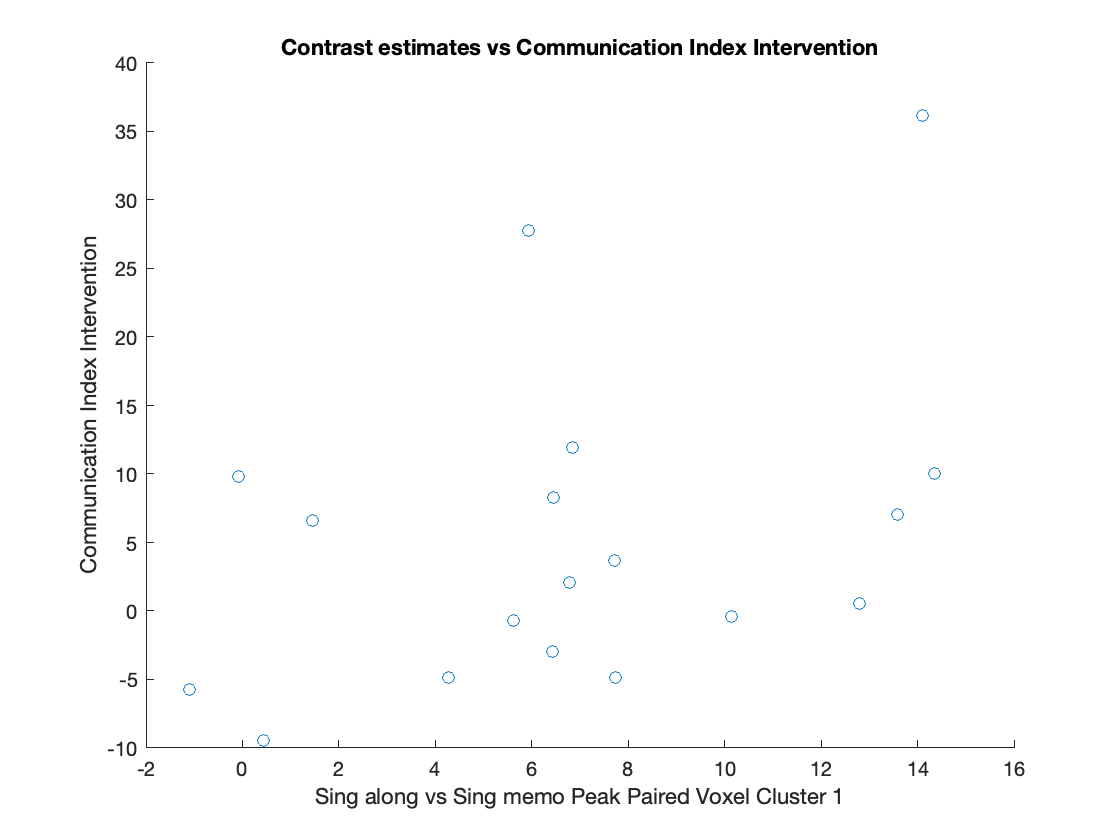

% Get the image filenames
filenames_contrast2= dir(fullfile(data_path,contrast2));
filenames_contrast2(ismember({filenames_contrast2.name},{'.','..'}))=[];
% Get peak voxel intensity for all patients
for i=1:size(filenames_contrast2,1)
    V=spm_vol(fullfile(data_path,contrast2,filenames_contrast2(i).name)); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    idx=find(XYZmm(1,:)==peak2(1,1) & XYZmm(2,:)==peak2(1,2) & XYZmm(3,:)==peak2(1,3)); %Get the intensity value for the peak
    XYZmm(:,idx);
    [Xvox, Yvox, Zvox]=ind2sub(size(Y(:,:,:,1)),idx);
    int=Y(Xvox,Yvox,Zvox,:);
    [~,name,ext] =fileparts(filenames_contrast2(i).name);
    pa_int_peak2{i,1}=str2num(name(end-1:end)); %Save the patient ID in BIDS
    pa_int_peak2{i,2}=int;% Save intensity value for the peak from all patients
end

%% Get behavioural values from the patients with existing images
ID_BIDS_pat=cell2mat(pa_int_peak2(:,1));
[idx_pat,iall,i] = intersect(ID_BIDS_all,ID_BIDS_pat);
Comm_Idx_int_pat_contrast2=Comm_Idx_int_all(iall,:);
Resp_Speech_Idx_int_pat_contrast2=Resp_Speech_Idx_int_all(iall,:);

% Remove patients with NaN values in behaviour
if sum(isnan(Comm_Idx_int_pat_contrast2(:,1)))~=0
    NAN_Index_contrast2=find(isnan(Comm_Idx_int_pat_contrast2(:,1)));
    Comm_Idx_int_pat_contrast2(NAN_Index_contrast2,:)=[];
    pa_int_peak2_comm=cell2mat(pa_int_peak2(:,2));
    pa_int_peak2_comm(NAN_Index_contrast2,:)=[];
end
%% Plot Intensity against behaviour for the peak coordinate
for p=1:size(peak2,1)
        y=Comm_Idx_int_pat_contrast2;
           if exist('pa_int_peak2_comm')==1
            x=pa_int_peak2_comm;
        else
            x=cell2mat(pa_int_peak2(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs Communication Index Intervention'), xlabel(['Sing along vs Sing memo Peak Paired Voxel Cluster ' num2str(p)]), ylabel ('Communication Index Intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_PairedT_SingavsSingmemo_Communication_Index_' num2str(p) '.jpg'])
        save('Communication_Index_int_singavssingm','x','y')
        CI_singavssingm_T=table(x,y);
        writetable(CI_singavssingm_T, 'CI_singavssingm_T.xlsx')
end


% Pearson correlation
[rho_peak2,pval_peak2] = corr(x,y,'Type','Pearson')

rho_peak2 = 0.3949

pval_peak2 = 0.1049

[rho_peak2,pval_peak2] = corr(x,y,'Type','Spearman')

rho_peak2 = 0.4035

pval_peak2 = 0.0980

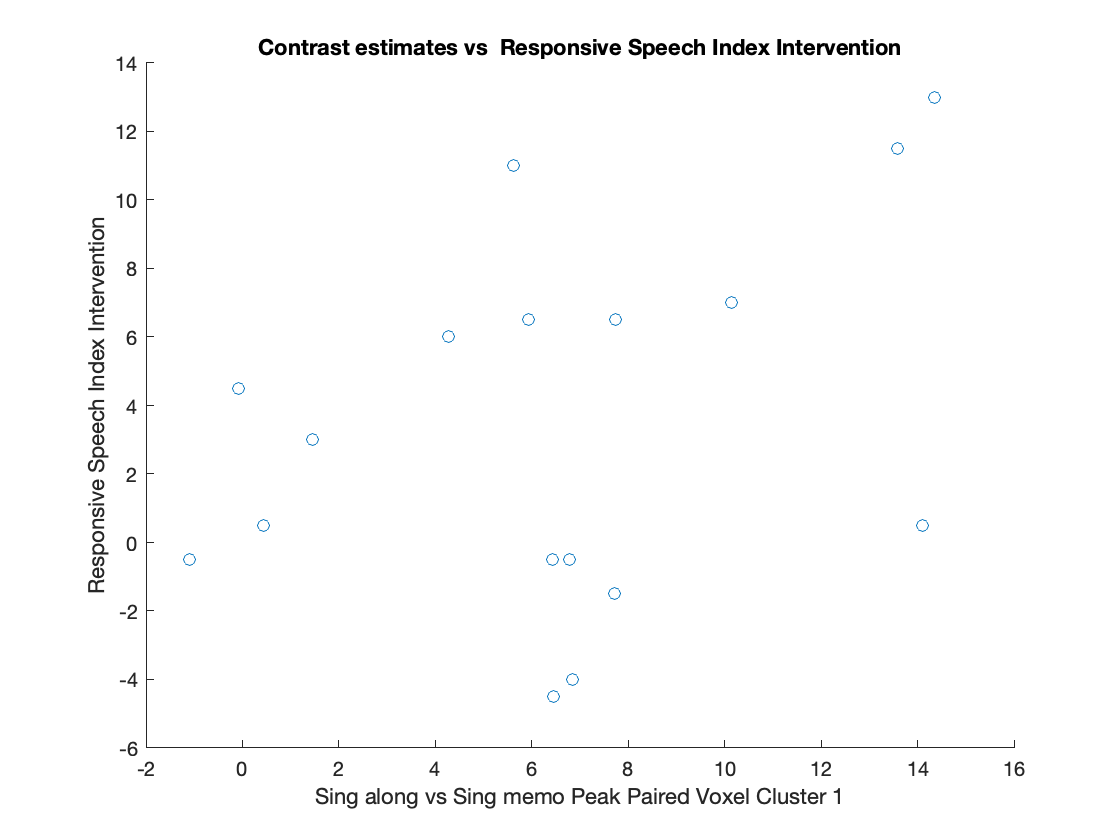


clear x y

% Remove patients with NaN values in behaviour
if sum(isnan(Resp_Speech_Idx_int_pat_contrast2(:,1)))~=0
    NAN_Index_contrast2=find(isnan(Resp_Speech_Idx_int_pat_contrast2(:,1)));
    Resp_Speech_Idx_int_pat_contrast2(NAN_Index_contrast2,:)=[];
    pa_int_peak2_resp=cell2mat(pa_int_peak2(:,2));
    pa_int_peak2_resp(NAN_Index_contrast2,:)=[];
end
%% Plot Intensity against behaviour for the peak coordinate
for p=1:size(peak2,1)
        y=Resp_Speech_Idx_int_pat_contrast2;
           if exist('pa_int_peak2_resp')==1
            x=pa_int_peak2_resp;
        else
            x=cell2mat(pa_int_peak2(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs  Responsive Speech Index Intervention'), xlabel(['Sing along vs Sing memo Peak Paired Voxel Cluster ' num2str(p)]), ylabel ('Responsive Speech Index Intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_PairedT_SingavsSingmemo_Responsive_Speech_Index_' num2str(p) '.jpg'])
        save('Responsive_Speech_Index_int_singavssingmemo','x','y')
        RSI_singavssingm_T=table(x,y);
        writetable(RSI_singavssingm_T, 'RSI_singavssingm_T.xlsx')
end


% correlation
[rho_peak2,pval_peak2] = corr(x,y,'Type','Pearson')

rho_peak2 = 0.3624

pval_peak2 = 0.1528

[rho_peak2,pval_peak2] = corr(x,y,'Type','Spearman')

rho_peak2 = 0.2230

pval_peak2 = 0.3880

clear x y
